preparing the .jsoncopy files with the LFP-data to the distinct "patients"-folder with a batch script ("copyjson.bat"):

*setlocal*

*set "source=C:\Users\User\Downloads\PerceptLFPs\Percept-Pat-LFP\PD071PH_sub-20210622PStn"*

*set "target=C:\Users\User\MATLAB Drive\masterthesis\Patient2"*

*for /r "%source%" %%f in (*.jsoncopy) do (*

*   echo kopiere %%f nach %target%*

*   copy "%%f" "%target%"*

*)*

*echo Alle dateien wurden kopiert!*

*endlocal*

clc; clear; close all;
% Initialize channel_labels variable (Treven, exportPSD.m):
channel_labels = {'LFP_Stn_0_1_LEFT_RING', 'LFP_Stn_0_2_LEFT_RING', 'LFP_Stn_0_3_LEFT_RING', ...
                  'LFP_Stn_1_2_LEFT_RING', 'LFP_Stn_1_3_LEFT_RING', 'LFP_Stn_2_3_LEFT_RING', ...
                  'LFP_Stn_0_1_RIGHT_RING', 'LFP_Stn_0_2_RIGHT_RING', 'LFP_Stn_0_3_RIGHT_RING', ...
                  'LFP_Stn_1_2_RIGHT_RING', 'LFP_Stn_1_3_RIGHT_RING', 'LFP_Stn_2_3_RIGHT_RING', ...
                  'LFP_Stn_1_A_1_B_LEFT_SEGMENT', 'LFP_Stn_1_B_1_C_LEFT_SEGMENT', 'LFP_Stn_1_A_1_C_LEFT_SEGMENT', ...
                  'LFP_Stn_2_A_2_B_LEFT_SEGMENT', 'LFP_Stn_2_B_2_C_LEFT_SEGMENT', 'LFP_Stn_2_A_2_C_LEFT_SEGMENT', ...
                  'LFP_Stn_1_A_1_B_RIGHT_SEGMENT', 'LFP_Stn_1_B_1_C_RIGHT_SEGMENT', 'LFP_Stn_1_A_1_C_RIGHT_SEGMENT', ...
                  'LFP_Stn_2_A_2_B_RIGHT_SEGMENT', 'LFP_Stn_2_B_2_C_RIGHT_SEGMENT', 'LFP_Stn_2_A_2_C_RIGHT_SEGMENT', ...
                  'LFP_Stn_1_A_2_A_LEFT_SEGMENT', 'LFP_Stn_1_B_2_B_LEFT_SEGMENT', 'LFP_Stn_1_C_2_C_LEFT_SEGMENT', ...
                  'LFP_Stn_1_A_2_A_RIGHT_SEGMENT', 'LFP_Stn_1_B_2_B_RIGHT_SEGMENT', 'LFP_Stn_1_C_2_C_RIGHT_SEGMENT'};

segment_labels = {'TWO_A_AND_TWO_B', 'ONE_A_AND_ONE_C', 'ZERO_AND_THREE'};

% Total number of channels
total_channels = length(channel_labels);

% Preallocate the psd_results_all and smoothed_psd_results_all cell arrays
% psd_results_all = cell(total_channels, num_files);
% smoothed_psd_results_all = cell(total_channels, num_files);
% detrended_psd_results_all = cell(total_channels, num_files);

## **section 1** - reading the data from 1 json file:

see: [https://www.youtube.com/watch?v=lyaIDHyOlFc&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=1&ab_channel=MATLAB](https://www.youtube.com/watch?v=lyaIDHyOlFc&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=1&ab_channel=MATLAB)

% filename = "LFP_testdata.json"
[filename, pathname] = uigetfile('*.json')
jsonText = fileread(strcat(pathname,filename))
data = jsondecode(jsonText)
num_files = 1
json_files = strcat(pathname, filename)
array2table

### Bulk read of .json files, choosing the patient´s folder:

% reading a bulk of files (Treven, exportPSD.m):
% Prompt a window to select a folder that contains all the '.mat' files
folder_path = uigetdir;

% Find all .json files in the folder and its subfolders
json_files = dir(fullfile(folder_path, '**/*.jsoncopy')); % '**/' is used to include subfolders

% Extract file names
json_files = arrayfun(@(x) fullfile(x.folder, x.name), json_files, 'UniformOutput', false)

% Filter file names containing "LMTD"
%json_files_LMTD = json_files(cellfun(@(x) contains(x, 'LMTD'), json_files));

% Remove file extensions (.mat) from the filtered file names
%mat_files_noext = cellfun(@(x) x(1:end-4), json_files_LMTD, 'UniformOutput', false);

% Extract datetime information from file names
%datetime_str = cellfun(@(x) x(end-15:end-2), json_files_noext, 'UniformOutput', false);
%dates = datetime(datetime_str, 'InputFormat', 'yyyyMMddHHmmss');

% Number of files
num_files = length(json_files)
% Preallocate the channel_side_all matrix
channel_side_all = nan(total_channels, num_files)

### Processing the LFP-Data (LFPFrequency and LFPMagnitude) for 1 JSON-File:

% check if a bulk read of the json files has been performed or only 1 JSON
% file has been read:
if ~exist('num_files', 'var')
    num_files = 1
end

num_files = 1

% Load LFP data from JSON:
if class(json_files)=='char'
    jsonText = fileread(json_files);
else % array of files:
    jsonText = fileread(json_files{1});
end

Unrecognized function or variable 'json_files'.

lfpdata = jsondecode(jsonText);
lfm = lfpdata.LFPMontage        % 1..12 or 1..30 struct (Strukturarray)
lfpMeasures = struct('SensingElectrodes',[], 'SensingValues',[], 'SensingDiff', [])
for i = 1:length(lfm)
    % adding the Magnitude values of the measurement to a struct:
    lfpMeasures(i).SensingElectrodes = strcat(extractAfter(lfm{i,1}.Hemisphere, '.'),' - ', extractAfter(replace(lfm{i,1}.SensingElectrodes,'_',' '),'.'));
    lfpMeasures(i).SensingValues = lfm{i,1}.LFPMagnitude;
    % test = (lfm(i).LFPMagnitude)
end 

% plot the data:
figure
hold on
% plot the absolute values:
for i = 1:length(lfpMeasures)
    plot(lfpMeasures(i).SensingValues);
end

legend(lfpMeasures(:).SensingElectrodes);
hold off
xlabel("frequency (Hz)")
ylabel("magnitude(µVp)")
title("LFP Montage all sensors, Patient 2", "Frequency vs. Magnitude")

## Printing the difference values of all 12 sensing electrodes to reference electrode (1st electrode-pair):

% code of gpt for calculating the differences of lfpMeasures.SensingValues
% and storing them in the corresponding field SensingDiff:
% Load the .mat file
%load('gpt_input_01092024.mat');

% Get the reference sensingValues from the first element
REFERENCE_ELECTRODE = 5

REFERENCE_ELECTRODE = 5

figureFilename = 'SensingDiffPlot_ref.pdf'

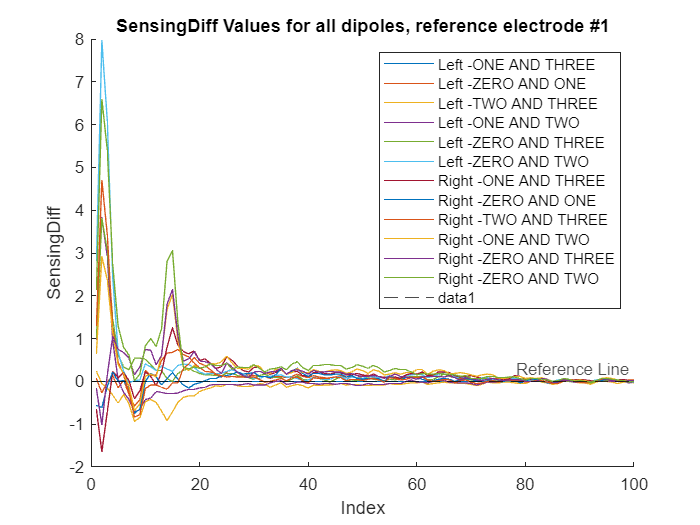

figureFilename = 'SensingDiffPlot_ref.pdf'

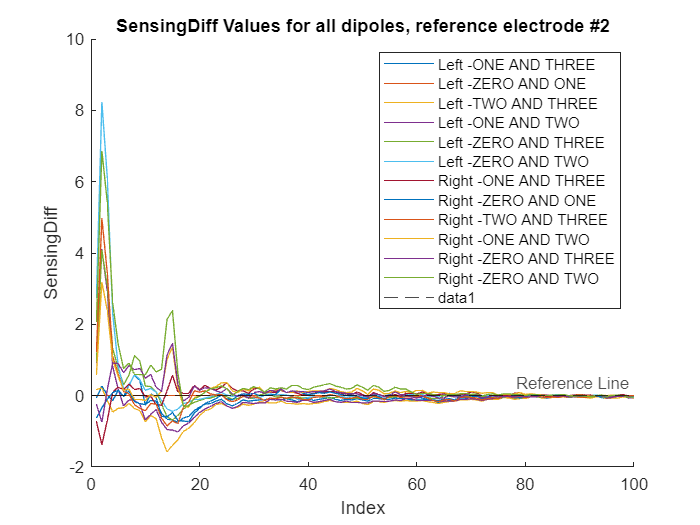

figureFilename = 'SensingDiffPlot_ref.pdf'

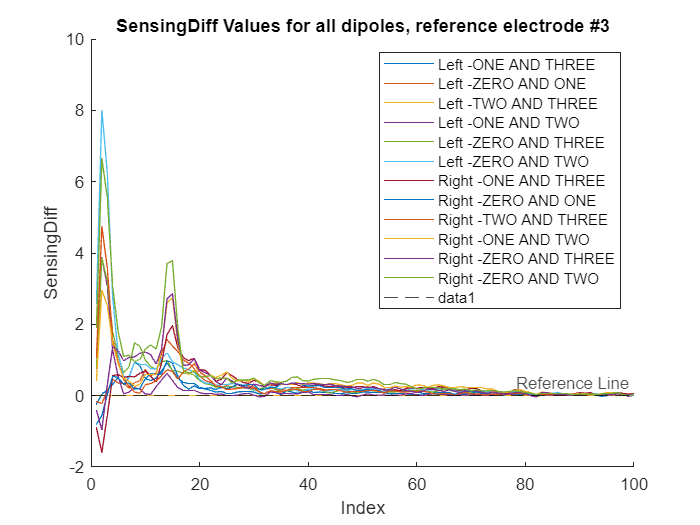

figureFilename = 'SensingDiffPlot_ref.pdf'

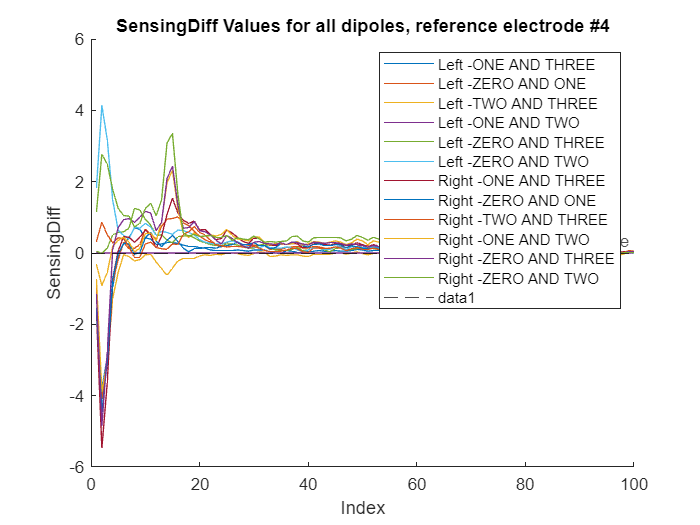

figureFilename = 'SensingDiffPlot_ref.pdf'

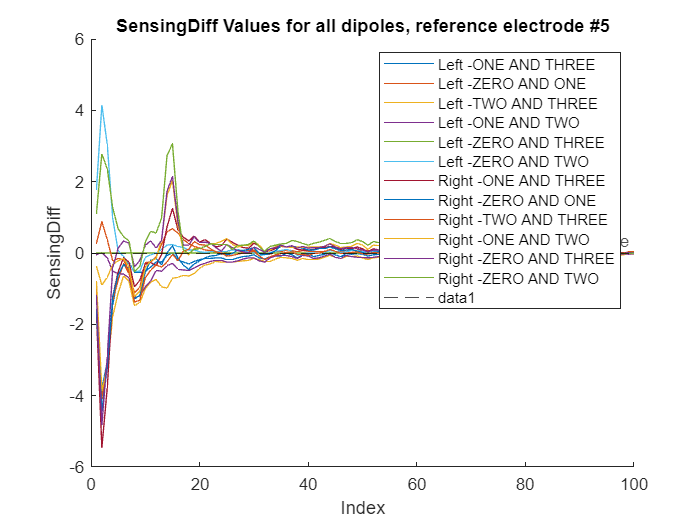

figureFilename = 'SensingDiffPlot_ref.pdf'

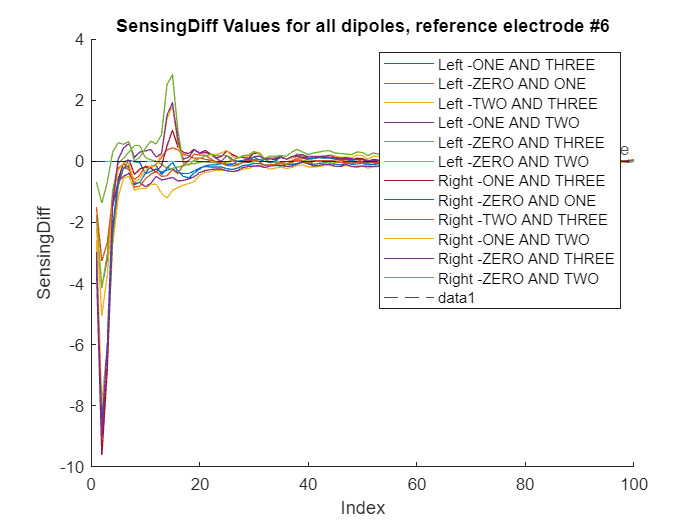

figureFilename = 'SensingDiffPlot_ref.pdf'

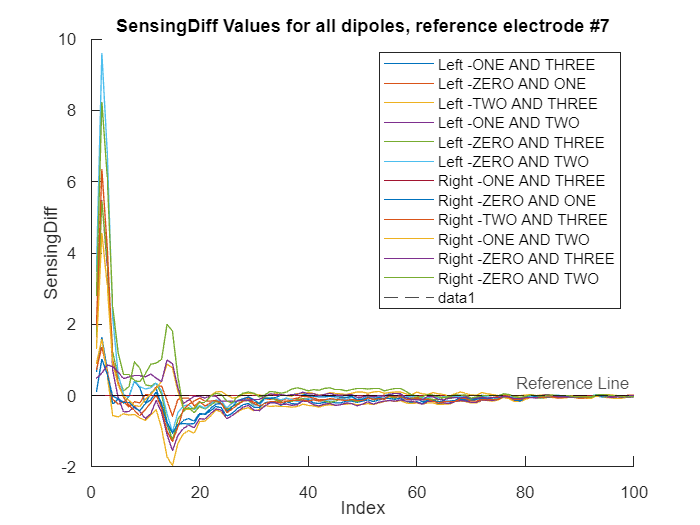

figureFilename = 'SensingDiffPlot_ref.pdf'

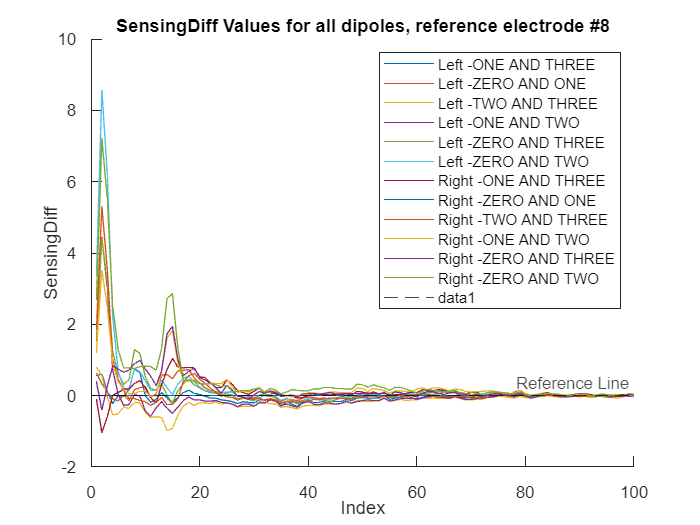

figureFilename = 'SensingDiffPlot_ref.pdf'

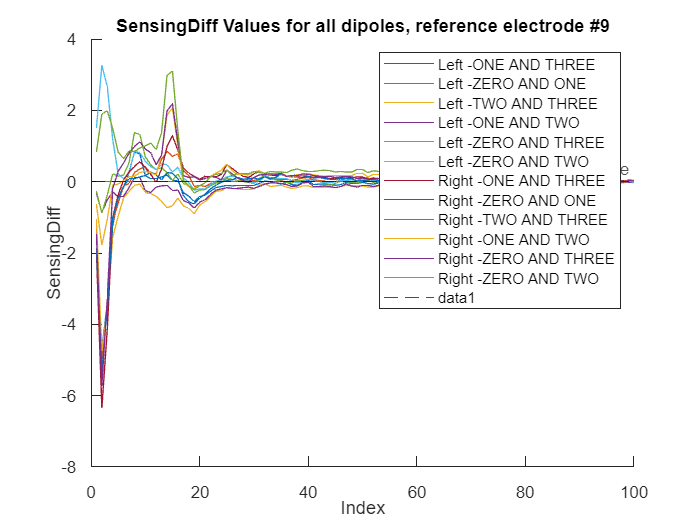

figureFilename = 'SensingDiffPlot_ref.pdf'

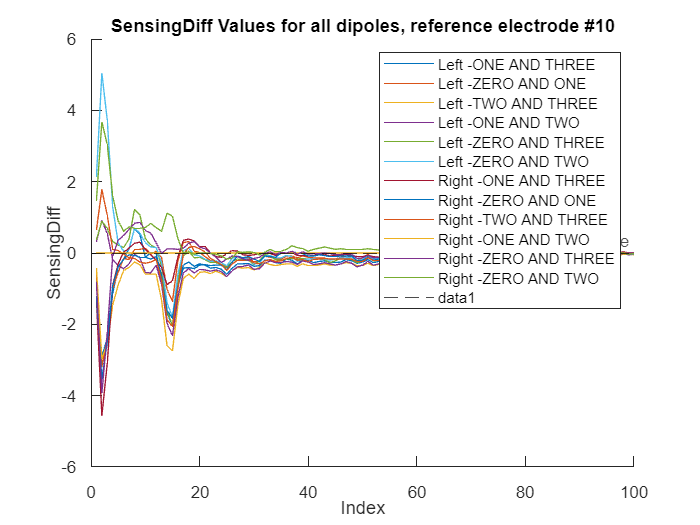

figureFilename = 'SensingDiffPlot_ref.pdf'

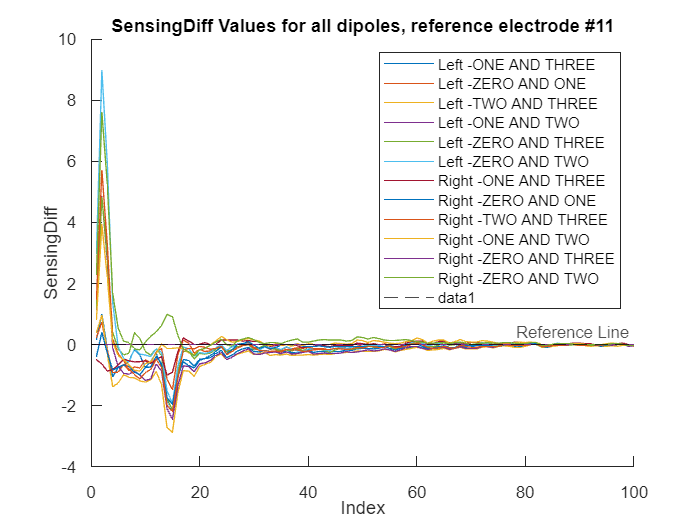

figureFilename = 'SensingDiffPlot_ref.pdf'

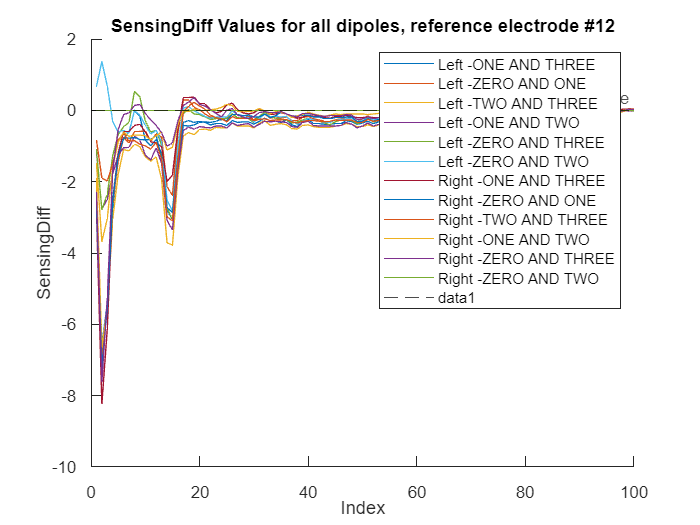


% loop thru all 12(?) electrode-/dipol-pairs zu calculate each difference
% and plot a figure of it:
for numElec = 1:length(lfpMeasures)
    REFERENCE_ELECTRODE = numElec;
    referenceValues = lfpMeasures(REFERENCE_ELECTRODE).SensingValues;

    % Loop through each element of the structure array
    for i = 1:length(lfpMeasures)
        % Calculate the difference with the reference sensingValues
        lfpMeasures(i).SensingDiff = lfpMeasures(i).SensingValues - referenceValues;
    end

    figure;
    % Hold the plot to overlay multiple lines
    hold on;

    % Loop through each struct to plot SensingDiff
    for i = 1:length(lfpMeasures)
        % Extract SensingDiff for the current struct
        sensingDiff = lfpMeasures(i).SensingDiff;
        % Plot SensingDiff
        plot(sensingDiff, 'DisplayName', lfpMeasures(i).SensingElectrodes)
    end

    % Add a reference line at y = 0
    yline(0, '--', 'Reference Line', 'Color', 'k');

    % Add labels and title
    xlabel('Index');
    ylabel('SensingDiff');
    strTitle="SensingDiff Values for all dipoles, reference electrode #"+num2str(REFERENCE_ELECTRODE);
    title(strTitle);
    legend('show'); % Show the legend with DisplayName

    % Release the hold on the plot
    hold off;
    % Save the current figure as a .fig file
    % figureFilename = strcat('SensingDiffPlot_ref', num2str(REFERENCE_ELECTRODE), '.pdf')
    figureFilename = strcat('SensingDiffPlot_ref',  ,'.pdf')
    % savefig(figureFilename);
    if numElec == 1
        exportgraphics(gcf, figureFilename , 'ContentType', 'vector');
    else
        exportgraphics(gcf,figureFilename,'Append',true)
    end
end

REFERENCE_ELECTRODE = 5
8



% subtract the value of the reference electrode (#1) from all Magnitudes:
lfpReference = lfpMeasures(REFERENCE_ELECTRODE).SensingValues;
for i = 1:length(lfpMeasures)
    lfpMeasures(i).SensingDiff = lfpMeasures(i).SensingValues - lfpReference;
    plot(lfpMeasures(i).SensingDiff);
    hold on
end
legend(lfpMeasures(:).SensingElectrodes);

hold off


% initializing the arrays for the magnitude and frequency values:
lfp_Frequency = cell(100,num_files);
lfp_Magnitude = cell(100,num_files);
first_file = 1;
last_file = num_files;

%% Iterating through each file to fill channel_side_all and calculate PSD
for file_idx = first_file:last_file
    % Load LFP data from JSON:
    jsonText = fileread(json_files{file_idx});
    lfpdata = jsondecode(jsonText);

    % Get the current number of channels from the loaded data
    % current_num_channels = size(lfpdata.data.label, 1);
    
    % Find the indices of the current channels in the total channels list
    % current_indices = find(ismember(lfpdata.LFPMontage{:}, segment_labels));

    % Fill channel_side_all with 1=left and 2=right
    % for j = 1:30
    %     if contains(lfpdata.LFPMontage{j,1}.Hemisphere, '.Left')
    %         channel_side_all(current_indices(j), file_idx) = 1; % 'L'
    %     elseif contains(lfpdata.LFPMontage{j,1}, '.Right')
    %         channel_side_all(current_indices(j), file_idx) = 2; % 'R'
    %     end
    % end

    % Get the LFP data for each channel (6x5288 double)
    
    % check, if LFP-Montage Data exists in the current json file:
    if isfield(lfpdata, 'LFPMontage')
        % lfm =lfpdata.LFPMontage(file_idx,1);
        lfm =lfpdata.LFPMontage
    else
        continue
    end

    test = getfield(lfm,'LFPMagnitude')
    numLFPMeasures = size(lfm)
    if iscell(lfm)
        % for i = 1:100
            lfp_Frequency{i,file_idx} = lfm{1,1}.LFPFrequency(i, 1);
            lfp_Magnitude{i,file_idx} = lfm{1,1}.LFPMagnitude(i, 1);
        % end
    else
        for i = 1:numLFPMeasures
            % [test] = lfm(i,1).LFPFrequency
            [lfp_Frequency{i,file_idx}] = cell2struct(lfm(i,1).LFPFrequency,1);
            [lfp_Magnitude{i,file_idx}] = [lfm(i,1).LFPMagnitude];
        end
    end
    % fs = lfpdata.data.fsample;

    % Compute the PSD for each channel and store the results
    % for channel_idx = 1:size(lfp_data, 1)
    %     % Get the current LFP data
    %     current_lfp = lfp_data(channel_idx, :);
    % 
    %     % Apply a high-pass filter at 5 Hz
    %     [b_high, a_high] = butter(4, 5 / (fs / 2), 'high');
    %     current_lfp_highpass = filtfilt(b_high, a_high, current_lfp);
    % 
    %     % Apply a low-pass filter at 90 Hz
    %     [b_low, a_low] = butter(4, 90 / (fs / 2), 'low');
    %     current_lfp_filtered = filtfilt(b_low, a_low, current_lfp_highpass);
    % 
    %     % Calculate PSD for the filtered LFP data
    %     [pxx, f] = pwelch(current_lfp_filtered, [], [], [], fs);  
    % 
    %     % Save the PSD results for the current channel in the corresponding
    %     % row and column of the psd_results_all cell array
    %     psd_results_all{current_indices(channel_idx), file_idx} = pxx;
    % 
    %     % Smooth the PSD data with a window size of x
    %     pxx_smoothed = smooth(pxx, 15);
    % 
    %     % Save the smoothed PSD results for the current channel in the
    %     % corresponding row and column of the smoothed_psd_results_all cell array
    %     smoothed_psd_results_all{current_indices(channel_idx), file_idx} = pxx_smoothed;
    % 
    %     % Detrend the log-transformed PSD data
    %     log_pxx = log10(pxx_smoothed);
    %     poly_coeffs = polyfit(f, log_pxx, 1);
    %     fitted_values = polyval(poly_coeffs, f);
    % 
    %     % Subtract the fitted values from the original log-transformed PSD data to obtain the detrended PSD data
    %     log_pxx_detrended = log_pxx - fitted_values;
    % 
    %     % Transform the detrended data back to its original scale by taking the exponent of the detrended data
    %     pxx_detrended = 10 .^ log_pxx_detrended;
    % 
    %     % Save the detrended PSD results for the current channel in the
    %     % corresponding row and column of the detrended_psd_results_all cell array
    %     detrended_psd_results_all{current_indices(channel_idx), file_idx} = pxx_detrended;
    % 
    % end
end
disp(lfp_Frequency)
disp(lfp_Magnitude)


## section 2 - data preprocessing

see: [https://www.youtube.com/watch?v=ais_Oj6Fx-E&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=2&ab_channel=MATLAB](https://www.youtube.com/watch?v=ais_Oj6Fx-E&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=2&ab_channel=MATLAB) select data of interest, drop unnessessery fields with e.g. personal data data = removevars(data, ["event_id", "source"]; data = movevars(data, ["aa", "bb"], "Before", "state") function maxk() -> finding value and index of a first k having max.values

% preprocess date and times
% function table2timetable(data): creates a timetable: every line is a....
% data.datefield.Format = "dd-MMM-yyyy HH:mm:ss";

% timestamp
% metadata: data.Properties
% explore the timerange: [tmin, tmax] = bounds(data.Time)
% categories: 
% data = PreprocessCategories(data)
% removecats(data.event_type), reordercats, mergecats
% lowercase: lower(data...)
% contains(data.stringvar, "searchtext") (gives back idx of entries, which
% containing the "searchtext".
% missing data:
%   - standardizeMissing
%   - ismissing
%   - rmmissing
%   - fillmissing
%
% work with OUTLIERS:
%   - isoutlier
%   - rmoutlier
%   - filloutliers
% smoothing data (make softer curves): smoothdata(data)
% synchronize data:
%
% mont = data.LFPMontage
figure
plot(lfp_Frequency, lfp_Magnitude);
hold on
for i=2:100
   plot(lfp_Frequency, lfp_Magnitude);
end
% hold off
xlabel("frequency (Hz)")
ylabel("magnitude(µVp)")
title("LFP Montage, Patient 2", "Frequency vs. Magnitude")


## displaying the data

% example code from Matlab-chatgpt (27.8.2024):

% Sample data
x = 1:10;         % X-axis values
y = rand(1, 10);  % Y-axis values

% Create a plot


xlabel('Custom X-axis');
ylabel('Random Values');
title('Custom X-axis Tick Labels Example');
plot(x, y, '-o');
% Define custom tick positions on the x-axis
xtick_positions = [1, 3, 5, 7, 9];

% Define custom tick labels corresponding to the positions
xtick_labels = {'A', 'B', 'C', 'D', 'E'};

% Apply custom ticks and labels to the plot
xticks(xtick_positions);           % Set the tick positions
xticklabels(xtick_labels);         % Set the tick labels

% Optional: Customize the appearance
set(gca, 'FontSize', 12);          % Set font size for better visibility
set(gca, 'XTickLabelRotation', 45); % Rotate tick labels if they overlap


## section 3 - analyzing data (in several different ways, e.g. changepoint detection)

see: [https://www.youtube.com/watch?v=I1EQx3O2qCk&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=3&ab_channel=MATLAB](https://www.youtube.com/watch?v=I1EQx3O2qCk&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=3&ab_channel=MATLAB) damageByEvent = groupsummary(data, parameters) grouptransform() retime() splitapply() changepoint detection (local minima/maxima): - islocalmin - islocalmax - ischange

## section 4 - Visualizing Data

Visualization types: - stackedplot(data) - heatmap() - geobubble() - wordcloud() - boxplot() - gscatter() - ...

figure bigfigure histogram(data.., parameters) xlabel("x-achse") ylabel("y-achse") title("title of diagram")

using "live controls"

## section 5 - Predictive modeling

see: [https://www.youtube.com/watch?v=BBtnVjVYI2k&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=5&ab_channel=MATLAB](https://www.youtube.com/watch?v=BBtnVjVYI2k&list=PLn8PRpmsu08o3O3NfbfySO5tQozfzuAy_&index=5&ab_channel=MATLAB) 

## section 6 - working with Big Data

## section 7 - deploying the model